# Ignore Headers and Fill Missing Values

Starting in R2020a, the `readtable` function read an input file as though it automatically called the `detectImportOptions` function on the file. It can detect data types, discard extra header lines, and fill in missing values.

For example, preview the file `headersAndMissing.txt` in a text editor. The file has a line with column names and another line with headers. The last two rows have gaps where the previous rows have data values.

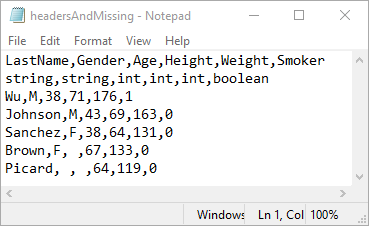

Create a table from the file. The `readtable` function discards the headers. Also, it fills in gaps with appropriate missing values—a `NaN` value for numeric variables, and an empty character vector for text.

T = readtable('headersAndMissing.txt')

To restore the default behavior from previous releases, specify the `'Format','auto'` name-value pair argument. `readtable` reads the headers as data, and as a result, it converts all the table variables to text.

T = readtable('headersAndMissing.txt','Format','auto')

For more information, see the Compatibility Considerations section on this page.

*Copyright 2019 The MathWorks, Inc.*